DataFile = ('/MATLAB Drive/MobileSensorData');
%https://matlab.fandom.com/wiki/FAQ#How_can_I_process_a_sequence_of_files.3F
filePattern = fullfile(DataFile, 'Step*.mat');
theFiles = dir(filePattern)

theFiles = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


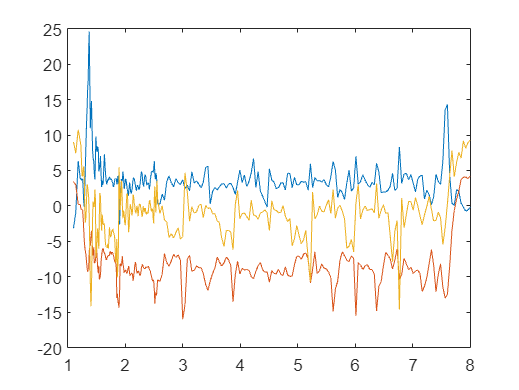

for k=1 : length(theFiles)
    baseFileName = theFiles(k).name;
    fullFileName = fullfile(theFiles(k).folder, baseFileName);
    
end
%Need to put it in the same timetable: same timebase
% Think about what data the classification needs
% Look at moving average for each variable (mean). Can add standard
% deviation. Look at minimum and max accel and orientation
% Break the data up into chunks
% 
%Create labels for classification


Seconds = datevec(Acceleration.Timestamp);
NumSec = Seconds(:,6);
Start = round(NumSec(1));
End = round(NumSec(end));
Duration = End-Start;
Xaxis = 1:1:Duration;

plot(Acceleration.Timestamp, Acceleration.X);
hold on
plot(Acceleration.Timestamp, Acceleration.Y);
hold on
plot(Acceleration.Timestamp, Acceleration.Z);
hold off
xticklabels(Xaxis)

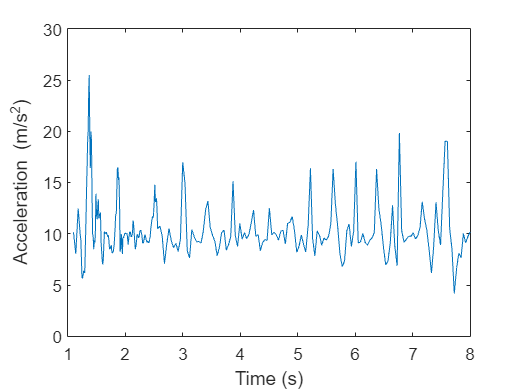






X = Acceleration.X;
Y = Acceleration.Y;
Z = Acceleration.Z;
mag = sqrt(sum(X.^2 + Y.^2 + Z.^2, 2));

plot(Acceleration.Timestamp, mag)
xticklabels(Xaxis)
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


magNoG = mag - mean(mag);

plot(Acceleration.Timestamp,magNoG);
xticklabels(Xaxis)
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


minPeakHeight = std(magNoG);

[pks,locs] = findpeaks(magNoG,'MINPEAKHEIGHT',minPeakHeight);

numSteps = numel(pks)

numSteps = 16

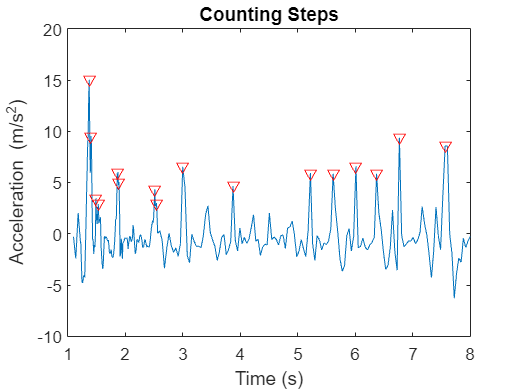

hold on;
plot(Acceleration.Timestamp(locs), pks, 'r', 'Marker', 'v', 'LineStyle', 'none');
title('Counting Steps');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
hold off;


m.AccelerationSensorEnabled = 0;

clear m;